clr;

obj = Gmodel('Bunny.stl');

* Loaded mesh = <a href="">Bunny.stl
</a>* Vertices  = 43.32k 
* Polycount = 86.63k 


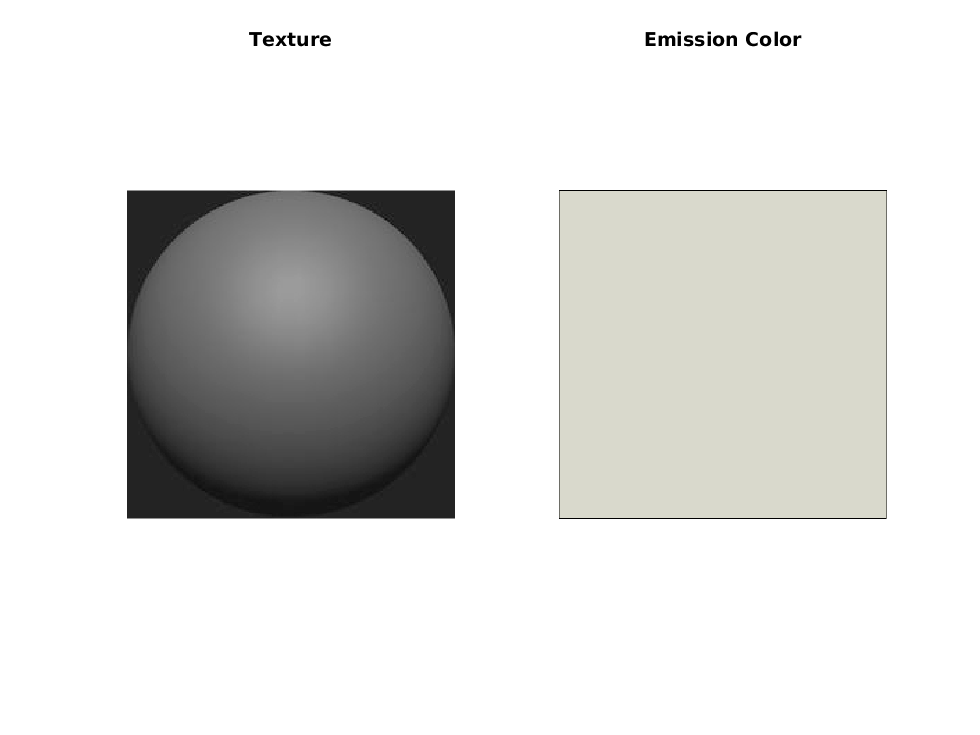

Texture  = grey; 
Emission = [0.85 0.85 0.80];

figure;
subplot(1,2,1); 
    image(Texture);
    axis equal;
    axis off;
    title('Texture');

subplot(1,2,2);
    showcolor(Emission);
    axis equal;
    axis off;
    title('Emission Color');

obj.set('Texture',Texture,...
        'Emission',Emission,...
        'SSS',true,...
        'SSSPower',1.50,...
        'SSSRadius',0.25);

obj.bake().render();

* Baking sub-surface scattering... (100 %) Done! 


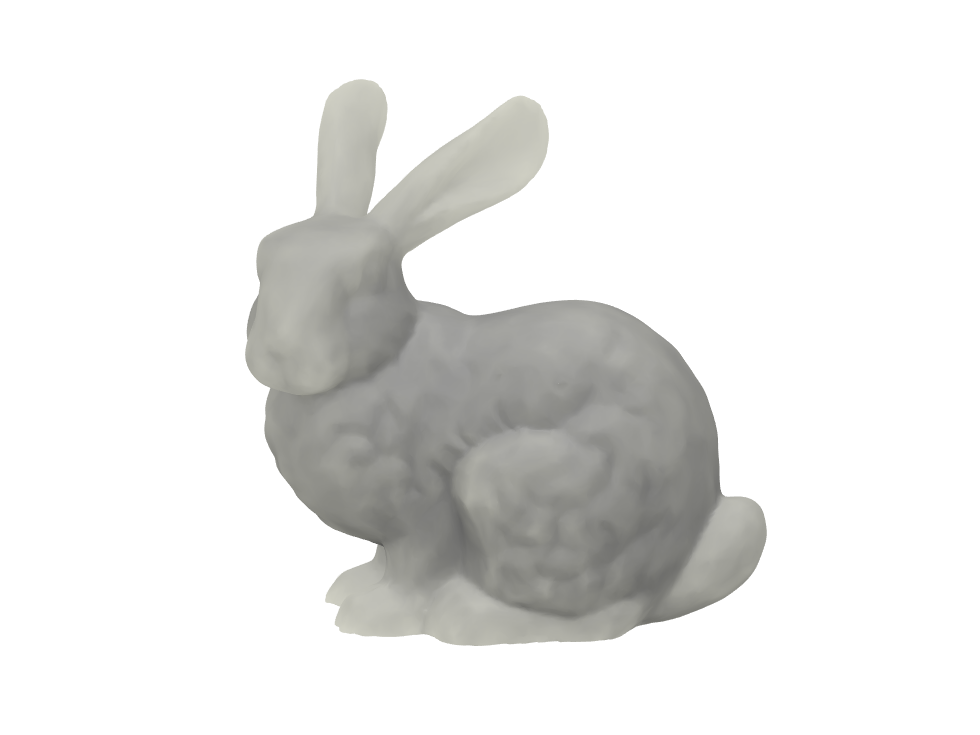


    view(0,15); 
    obj.update();

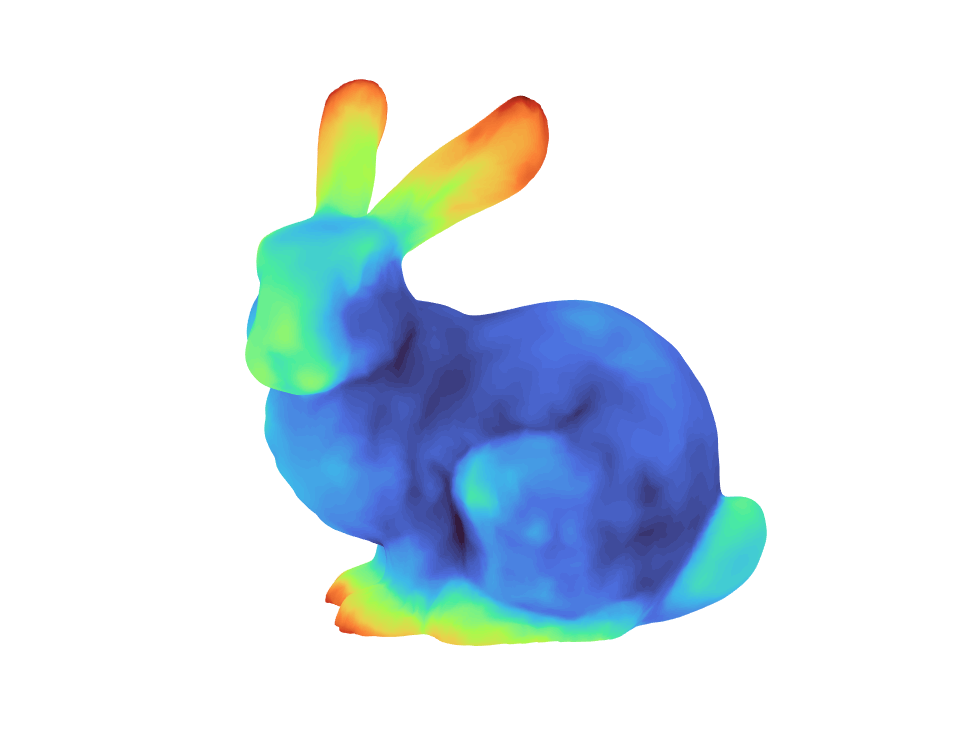

obj.showMap('SSS');